# Dryer Design Homework

Kathryn Atherton

ABE 55700

10/19/2018

clc;
clear;
close all;

## Problem 9.6-3: Prediction in Constant-Rate Drying Region. 

A granular insoluble solid material wet with water is being dried in the constant-rate period in a pan 0.61 m x 0.61 m and the depth of material is 25.4 mm. The sides and bottom are insulated. Air flows parallel to the top drying surface at a velocity of 3.05 m/s and has a dry bulb temperature of 60 degrees C and wet bulb temperature of 29.4 degrees C. The pan contains 11.34 kg of dry solid having a free moisture content of 0.35 kg H2O/kg dry solid, and the material is to be dried in the constant-rate period to 0.22 kg H2O/kg dry solid. 

width = 0.61; % m
length = 0.61; % m
depth = 25.4; % mm
depth = depth / 1000; % m
velocity = 3.05; % m/s
Tdb = 60; % deg C
Twb = 29.4; % deg C
Ls = 11.34; % kg
X1 = 0.35; % kg H20/kg dry solid
X2 = 0.22; % kg H20/kg dry solid

a) Predict the drying rate and the time in hours needed.

humidity = 0.0135; % kg H2O vapor / kg dry air, from figure 9.3-2
vh = (2.83e-3 + 4.45e-3 * humidity) * (Tdb + 273); % humid volume, m3/kg dry air
rho = (1.0 + humidity)/vh; % density of air, kg/m^3
G = rho * velocity * 3600; % kg/h.m^2
h = 0.0204 * G ^ 0.8; % W/m^2.K
lambda_w = 2432.2; % kJ/kg, from steam tables
A = length * width; % m^2
Rc = h / (lambda_w * 1000) * (Tdb - Twb) * 3600; % kg/h.m^2
fprintf('The drying rate is %f kg/h.m^2.\n', Rc * A);

The drying rate is 0.612030 kg/h.m^2.


time = (-Ls / A) * ((X2 - X1) / Rc); % h
fprintf('The drying time is %f hours.\n', time)

The drying time is 2.408706 hours.


b) Predict the time needed if the depth of material is increased to 44.5 mm.

depth_new = 44.5; % mm
depth_new = depth_new / 1000; % m
ratio = depth / depth_new;
time_new = time / ratio; % hours
fprintf('The new drying time is %f hours.\n', time_new)

The new drying time is 4.219976 hours.


## Problem 9.7-2: Drying Tests with a Foodstuff.

In order to test the feasibility of drying a certain foodstuff, drying data were obtained in a tray dryer with air flow over the top exposed surface having an area of 0.186 m^2. The bone-dry sample weight was 3.765 kg dry solid. At equilibrium after a long period, the wet sample weight was 3.955 kg H2O + solid. Hence, 3.955 - 3.765, or 0.190, kg of equilibrium moisture was present. The following sample weights versus time were obtained in the drying test: 

time = [0, 0.4, 0.8, 1.4, 2.2, 3.0, 4.2, 5.0, 7.0, 9.0, 12.0]; % h
weight = [4.944, 4.885, 4.808, 4.699, 4.554, 4.404, 4.241, 4.150, 4.019, 3.978, 3.955]; % kg
A = 0.186; % m^2
Ls = 3.765; % kg
Lw = 3.955; % kg
mc = Lw - Ls; % kg

a) Calculate the free moisture content X kg H2O/kg dry solid for each data point and plot X versus time. (Hint: for 0 h, 4.944 - 0.190 - 3.765 = 0.989 kg free moisture in 3.765 kg dry solid. Hence, X - 0.989/3.765.)

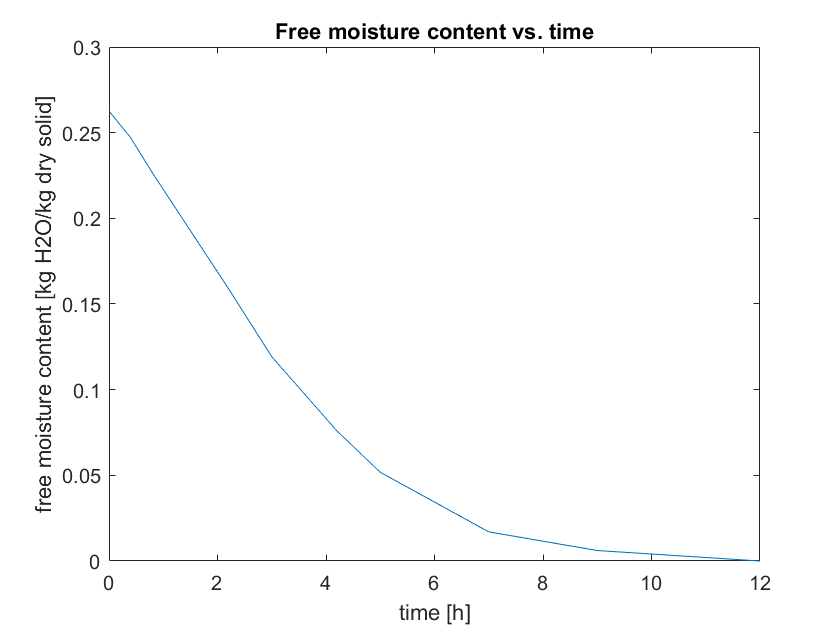

x = (weight - mc - Ls) ./ Ls; % kg
figure
plot(time, x)
title('Free moisture content vs. time')
xlabel('time [h]')
ylabel('free moisture content [kg H2O/kg dry solid]')

b) Measure the slopes, calculate the drying rates R in kg H2O/h.m^2, and plot R versus X. 

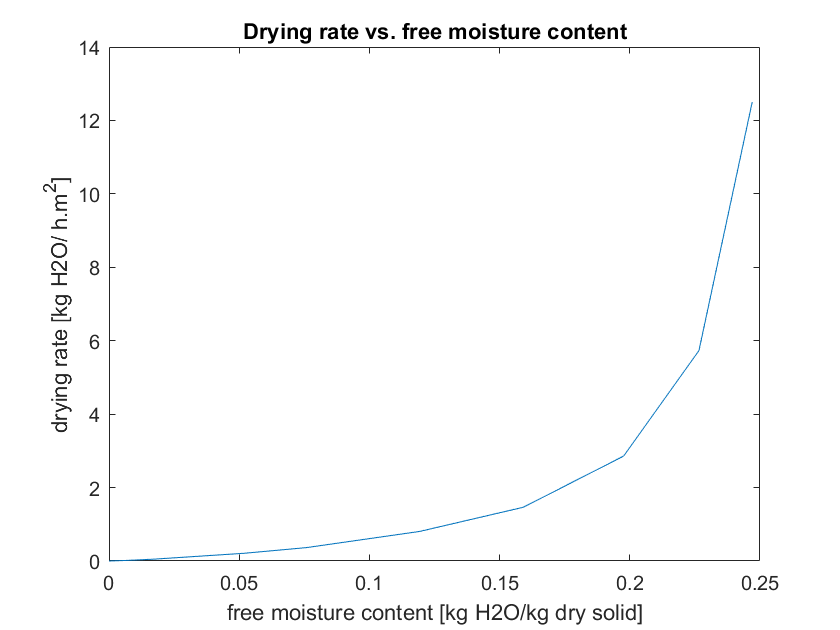

R = x .* Ls ./ (A .* time);
figure
plot(x,R)
title('Drying rate vs. free moisture content')
xlabel('free moisture content [kg H2O/kg dry solid]')
ylabel('drying rate [kg H2O/ h.m^2]')

c) Using this drying-rate curve, predict the total time to dry the sample from X = 0.20 to X = 0.04. Use numerical integration for the falling-rate period. What are the drying rate Rc in the constant-rate period and Xc?

 At X = 0.2 kg H2O/ kg dry solid, R = 6.66 kg/h.m^2

 At X = 0.04 kg H2O/ kg dry solid, R = 0.4 kg/h.m^2

 R = mX + c

 6.66 = m * 0.2 + c

 0.4 = m * 0.04 + c

m =(6.66 - 0.4) / (0.2 - 0.04);
c = 6.66 - (m * 0.2); 


$$\begin{array}{l}
R=\frac{-w_s }{A}\frac{\mathrm{dX}}{\mathrm{dt}}\\
\mathrm{dt}=\frac{-w_s }{A}\frac{\mathrm{dX}}{R}\\
\mathrm{dt}=\frac{-w_s }{A}\frac{\mathrm{dX}}{\mathrm{mX}+c}
\end{array}$$



$$\begin{array}{l}
t=\int_{0\ldotp 04}^{0\ldotp 2} \frac{-w_s }{A}\frac{\mathrm{dZ}}{Z}\\
Z=\mathrm{mX}+c\\
\mathrm{dX}=\frac{\mathrm{dZ}}{m}\\
Z=4\ldotp 01\;\mathrm{when}\;X=0\ldotp 04\\
Z=6\ldotp 66
\end{array}$$


t = Ls / A * 1/m * (log(6.66) - log(0.401)); % hours
fprintf('The time to dry in the falling rate period is %f hours.\n', t)

The time to dry in the falling rate period is 1.453753 hours.


fprintf('From the graph, the constant drying rate is 12.5 kg/h.m^2 and the Xc is 0.2470 kg H2O/kg dry solid.\n')

From the graph, the constant drying rate is 12.5 kg/h.m^2 and the Xc is 0.2470 kg H2O/kg dry solid.


## Problem 9.8-1: Drying of Biological Material in Tray Dryer

A granular biological material wet with water is being dried in a pan 0.305m x 0.305 m and 38.1 mm deep. The material is 38.1 mm deep in the pan, which is insulated on the sides and the bottom. Heat transfer is by convection from an air stream flowing parallel to the top surface at a velocity of 3.05 m/s, having a temperature of 65.6°C and humidity H = 0.010 kg H2O / kg dry air. The top surface receives radiation from steam-heated pipes whose surface temperature TR = 93.3°C. The emissivity of the solid is E = 0.95. It is desired to keep the surface temperature of the solid below 32.2°C so that decomposition will be kept low. Calculate the surface temperature and the rate of drying for the constant-rate period. 

width = 0.305; % m
length = 0.305; % m
depth = 38.1; % mm
depth = depth / 1000; % m
velocity = 3.05; % m/s
T = 65.6; % deg C
H = 0.010; % kg H2O/kg dry air
TR = 93.3; % deg C
E = 0.95;
T_desired = 32.2; % deg C

vh = (2.83e-3 + 4.56e-3 * H) * T; % m^3/kg dry air
rho = (1.0 + H)/vh; % density of air, kg/m^3
G = rho * vh * 3600; % kg / h.m^2
hc = 0.0204 * G ^ 0.8; % W/m^2.K
Uk = 0; % bottom insulated, no conduction
h = exp(1) * 5.676 * (((TR+273)/100)^4 - ((T_desired + 273)/100)^4)/(TR - T_desired); % W/m^2K
cs = (1.005 + 1.88 * H) * 10^3; % J/kg.K


$$\frac{H_s -H}{c_s }h_s =\left(1+\frac{U}{h_c }\right)\left(T-T_S \right)+\frac{h_R }{h_c }\left(T_R -T_S \right)$$


Ts = 31.3; % deg C, assumption
hs = 2429e3; % J/kg
Hs = 0.0305; 
Rc = ((hc + Uk) * (T - Ts) + h * (TR - Ts)) / hs; % kg H2O/h.m^2
fprintf('The estimated surface temperature is %f degrees C and the drying rate is %f kg H2O/h.m^2.\n', Ts, Rc)

The estimated surface temperature is 31.300000 degrees C and the drying rate is 0.000804 kg H2O/h.m^2.


## Problem 9.9-3: Diffusion Coefficient.

Experimental drying data of a typical nonporous biological material obtained under constant drying conditions in the falling-rate region are tabulated below. Drying from one side occurs with the material having a thickness of 10.1 mm. The data appear to follow the diffusion equation. Determine the average diffusivity over the range X/Xc = 1.0-0.10. 

x_xc = [1.00, 0.65, 0.32, 0.17, 0.10, 0.06]; 
t = [0, 2.5, 7.00, 11.4, 14.0, 16.0];
thickness = 10.1; % mm
thickness = thickness / 1000; % m
DL = 4 .* thickness ^ 2 ./ (pi ^ 2 .* t) .* log (8 .* x_xc ./ pi^2); 
avg_dl = mean(DL);
fprintf('The average diffusivity is %f m^2/s.\n', avg_dl)

The average diffusivity is -Inf m^2/s.


## Problem 9.10-5: Drying in a Continuous Tunnel Dryer.

A rate of feed of 700 Ibm dry solid/h containing a free moisture content of X1 = 0.4133 Ib H2O/lb dry solid is to be dried to X2 = 0.0374 lb H20/lb dry solid in a continuous counterflow tunnel dryer. A flow of 13,280 Ibm dry air/h enters at 203°F with an H2 = 0.0562 Ib H2O/lb dry air. The stock enters at the wet bulb temperature of 119°F and remains essentially constant in temperature in the dryer. The saturation humidity at 119°F from the humidity chart is Hw = 0.0786 Ib H20/lb dry air. The surface area available for drying is (A/Ls) = 0.30 ft^2/lbm dry solid. A small batch experiment was performed using constant drying conditions, air velocity, and temperature of the solid approximately the same as in the continuous dryer. The equilibrium critical moisture content was found to be Xc = 0.09591b H20/lb dry solid, and the experimental value of kyMb was found as 30.15 Ibm air/h· ft^2. In the falling-rate period, the drying rate was directly proportional to X. For the continuous dryer, calculate the time in the dryer in the constant-rate zone and in the falling-rate zone. 

(Ans: Hc = 0.0593 lb H2O/lb H2O/lb dry air, H1 = 0.0760 lb H2O/lb dry air, t = 4.24 h in the constant-rate zone, t = 0.47 h in the falling-rate zone)

feed = 700; % lbm dry solid/h
X1 = 0.4133; % lb H2O/lb dry solid 
X2 = 0.0374; % lb H2O/lb dry solid
air_flow = 13280; % lbm dry air / h
air_temp = 203; % deg F
H2 = 0.0562; % lb H2O/lb dry air
wb_T = 119; % deg F
Hw = 0.0786; % lb H2O/lb dry air
SA = 0.30; % ft^2/lbm dry solid
Xc = 0.0959; % lb H2O/lb dry solid
kymb = 30.15; % lbm air / h.ft^2
delHLM = 0.00826;
Hc = 0.0593;
t = air_flow / feed / SA / kymb * (Hw - Hc)/delHLM;
fprintf('The time for the contant rate period is %f hours.\n', t)

The time for the contant rate period is 4.900820 hours.


t = air_flow / feed / SA * Xc / kymb * 1 / (((Hw - Hc) * air_flow)/feed + X2) * log((Xc * (Hw - H2))/(X2 * (Hw - Hc)));
fprintf('The time for the falling rate period is %f hours.\n', t)

The time for the falling rate period is 0.543596 hours.


## Problem 9.10-6: Air recirculation in a Continuous Dryer.

The wet feed material to a continuous dryer contains 50 wt % water on a wet basis and is dried to 27 wt % by countercurrent air flow. The dried product leaves at the rate of 907.2 kg/h. Fresh air to the system is at 25.6°C and has a humidity of H = 0.007 kg H20/kg dry air. The moist air leaves the dryer at 37.8°C and H = 0.020 and part of it is recirculated and mixed with the fresh air before entering a heater. The heated mixed air enters the dryer at 65.6°C and H = 0.010. The solid enters at 26.7°C and leaves at 26.7°C, Calculate the fresh-air flow, the percent air leaving the dryer that is recycled, the heat added in the heater, and the heat loss from the dryer. 

(Ans: 32094 kg fresh dry air /h, 23.08% recycled, 440.6 kW in heater)

X1 = 0.5; % wt percent water
X2 = 0.27; % wt percent water
R = 907.2; % kg/h
dryair_T = 25.6; % deg C
Hdry = 0.007; % kg H2O/kg dry air
moistair_T = 37.8; % deg C
Hmoist = 0.020;
mixair_T = 65.5; % deg C
Hmix = 0.010;
solid_T = 26.7; % deg C
product = (0.73 * R);


$$H_{\mathrm{recycle}} G_{\mathrm{recycle}} +H_{\mathrm{fresh}} G_{\mathrm{fresh}} =H_{\mathrm{mix}} \left(G_{\mathrm{recycle}} +G_{\mathrm{fresh}} \right)$$



$$H_{\mathrm{mix}} \left(G_{\mathrm{recycle}} +G_{\mathrm{fresh}} \right)+P_{\mathrm{in}} X_1 =H_{\mathrm{recycle}} \left(G_{\mathrm{recycle}} +G_{\mathrm{fresh}} \right)+P_{\mathrm{out}} X_2$$


Gfresh = 32094; % kg/h
Grecycle = 9630; % kg/h
perc_recycle = Grecycle/(Gfresh-Grecycle) * 100; 
fprintf('The fresh air flow is %f kg/h.\n', Gfresh);

The fresh air flow is 32094.000000 kg/h.


fprintf('The recycled percent is %f percent.\n', perc_recycle)

The recycled percent is 42.868590 percent.


cs = (1.005 + 1.88 * Hdry); % kJ/kg dry air K


$$\begin{array}{l}
H_G =c_s \left(T_G -T_o \right)+{\mathrm{Hh}}_o \\
G_1 H_{\mathrm{G1}} +G_2 H_{\mathrm{G2}} +Q_H =\left(G_1 +G_2 \right)H_{\mathrm{G3}} 
\end{array}$$


QH = 440.6; % kW
fprintf('The heat added to the heater is %f kW.\n', QH)

The heat added to the heater is 440.600000 kW.



$$\left(G_1 +G_2 \right)H_{\mathrm{G3}} +{\mathrm{PH}}_1 =\left(G_1 +G_2 \right)H_{\mathrm{G2}} +{\mathrm{PH}}_2 +Q_{\mathrm{dry}}$$


Qdry = 44.7; % kW
fprintf('The heat lost from the dryer is %f kW.\n', Qdry)

The heat lost from the dryer is 44.700000 kW.


## Derivation 1


$$\begin{array}{l}
q_{\mathrm{in}} =\frac{k}{\Delta L}\left(T_s -T_f \right)\\
q_{\mathrm{out}} =h\left(T_e -T_s \right)\\
q_{\mathrm{out}} -q_{\mathrm{in}} =\frac{\left(T_s -T_f \right)}{\frac{1}{h}+\frac{k}{\Delta L}}\\
N_{a,\mathrm{in}} =\frac{D}{\mathrm{RT}\Delta L}\left(p_{\mathrm{fw}} -p_{\mathrm{sw}} \right)\\
N_{a,\mathrm{out}} =k_g \left(p_{\mathrm{sw}} -p_{\mathrm{ew}} \right)\\
N_{a,\mathrm{out}} -N_{a,\mathrm{in}} =\frac{\left(p_{\mathrm{fw}} -p_{\mathrm{ew}} \right)}{\frac{1}{k_g }+\frac{\left(\mathrm{RT}\Delta L\right)}{D}}\\
q=\Delta H_s N_a \\
\frac{\left(T_e -T_f \right)}{\frac{1}{h\;}+\frac{k}{\Delta L}}={\mathrm{dH}}_s \frac{\left(p_{\mathrm{fw}} -p_{\mathrm{ew}} \right)}{\frac{1}{k_g }+\frac{\left(\mathrm{RT}\Delta L\right)}{D}}\\
N_a =\frac{L}{2}\frac{1}{M_A V_S }\left(-\frac{\mathrm{dx}}{\mathrm{dt}}\right)\\
\frac{\left(p_{\mathrm{fw}} -p_{\mathrm{ew}} \right)}{\frac{1}{k_g }+\frac{\left(\mathrm{RT}\left(1-x\right)L\right)}{2D}}=\frac{L}{2}\frac{1}{M_A V_S }\left(-\frac{\mathrm{dx}}{\mathrm{dt}}\right)\\
t_{\mathrm{freeze}\;\mathrm{dry}} =\frac{L^2 }{4{\mathrm{kV}}_s }\frac{\Delta H_s }{M_a }\frac{1}{T_e -T_f }\left(x_1 -x_2 -\frac{x_1^2 }{2}-\frac{x_2^2 }{2}\right)
\end{array}$$


## Derivation 2:

Assuming no shrinkage 


$$V_{S\;} =\frac{h}{\lambda_w }\left(T_A -T_S \right)$$



$$\frac{X}{X_c }=8e^{D_L {t\left(\frac{\pi }{2}\right)}^2 } \left(T_A -T_S \right)$$



$$\frac{\mathrm{dX}}{\mathrm{dt}}=\frac{\pi^2 D_L X}{4x^2 }$$



$$R_F =-\frac{L_S }{4x^2 }\frac{\mathrm{dX}}{\mathrm{dt}}=$$

$$\frac{\pi^2 D_L L_S X}{4x^2 }$$



$$R_C =R_F \;\mathrm{at}\;X_C$$



$$\frac{h}{\lambda_W }\left(T_A -T_S \right)=X_C \frac{\left(-L_S \pi^2 D_L \right)}{4x^2 }$$



$$X_C =$$

$$\frac{h}{\lambda_w }\left(T_A -T_S \right)\frac{\left(-4x^2 A\right)}{-L_S \pi^2 D_L }$$


Assuming complete shrinkage


$$V_{\mathrm{total}} =V_L +V_S$$



$$V_C =\left(\frac{X_C }{\rho_w }\right)+\left(\frac{1}{\rho_S }\right)$$



$$\begin{array}{l}
V_O =\left(\frac{X_O }{\rho_w }\right)+\left(\frac{1}{\rho_S }\right)\\
\frac{x_c }{x_o }=\frac{V_c }{V_o }=\frac{\left(\frac{X_C }{\rho_w }\right)+\left(\frac{1}{\rho_S }\right)}{\left(\frac{X_O }{\rho_w }\right)+\left(\frac{1}{\rho_S }\right)}
\end{array}$$



$$X_c =\frac{V_C }{V_o }X_o$$



$$X_C =\frac{h}{\lambda_w }\left(T_A -T_S \right)\frac{-4{A\left(\left(\left(\frac{X_C }{\rho_w }\right)+\left(\frac{1}{\rho_S }\right)\right)x_o \right)}^2 }{L_S D_L \pi^2 }$$
